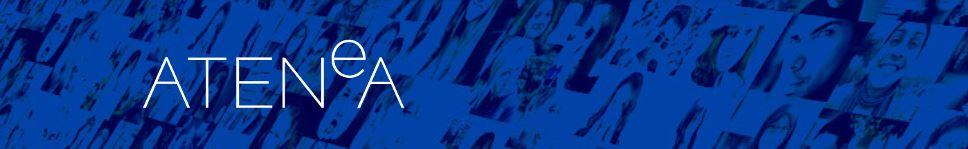

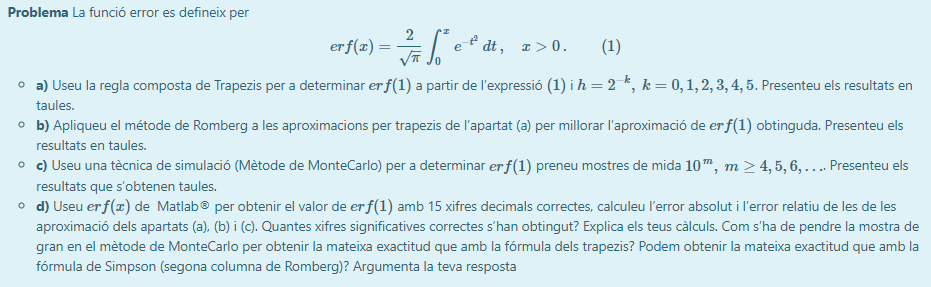

## Pràctica 3

clearvars
format shortG
f = @(t) 2/sqrt(pi)*exp(-t.^2);
ve = integral(f,0,1)

ve =        0.8427


`(a)`

% Métode de Trapezis
k = 0:5; TT = [];
n = length(k);
for i = 1:n
    h = 1/(2^k(i));
    x = 0:h:1; y = f(x);
    w = [1 2*ones(1,length(y)-2) 1];
    valor = sum(y.*w*(h/2));
    TT = [TT; k(i), h, valor, abs(valor-ve)];
end
taula = array2table(TT,'VariableNames',{'k','h','erf(1)','error'}); disp(taula)

    k       h       erf(1)       error   
    _    _______    _______    __________

    0          1    0.77174      0.070957
    1        0.5    0.82526      0.017438
    2       0.25    0.83837      0.004333
    3      0.125    0.84162     0.0010816
    4     0.0625    0.84243    0.00027029
    5    0.03125    0.84263    6.7565e-05



`(b)`

% Métode de Romberg
R = romberg(f,0,1,6);
R(:,end-1) = []; R(:,end) = [];
RT = [(0:n-1)',1./2.^(0:n-1)',R];
taula = array2table(RT,'VariableNames',{'k','h','R_1','R_2','R_3','R_4'}); disp(taula)

    k       h         R_1        R_2        R_3       R_4  
    _    _______    _______    _______    _______    ______

    0          1    0.77174          0          0         0
    1        0.5    0.82526     0.8431          0         0
    2       0.25    0.83837    0.84274    0.84271         0
    3      0.125    0.84162     0.8427     0.8427    0.8427
    4     0.0625    0.84243     0.8427     0.8427    0.8427
    5    0.03125    0.84263     0.8427     0.8427    0.8427



% Error absolut Romberg 
ERT = [(0:n-1)',1./2.^(0:n-1)',tril(abs(R-ve))];
taula = array2table(ERT,'VariableNames',{'k','h','ER_1','ER_2','ER_3','ER_4'}); disp(taula)

    k       h          ER_1          ER_2          ER_3          ER_4   
    _    _______    __________    __________    __________    __________

    0          1      0.070957             0             0             0
    1        0.5      0.017438    0.00040204             0             0
    2       0.25      0.004333    3.5258e-05    1.0807e-05             0
    3      0.125     0.0010816    2.2429e-06     4.186e-08    1.2901e-07
    4     0.0625    0.00027029    1.4062e-07    4.7075e-10    1.8623e-10
    5    0.03125    6.7565e-05    8.7952e-09    6.7419e-12    6.2328e-13



`(c)`

% Métode de Montecarlo
format longG
a = 0; b = 1;
MT = zeros(5,4);
for k = 4:8
    m = 10^k;
    x = a+(b-a)*rand(m,1);
    valor = sum(f(x))/m;
    MT(k-3,:) = [k, m, valor, abs(valor-ve)];
end
taula = array2table(MT,'VariableNames',{'k','M','erf(1)','error'}); disp(taula)

    k        M             erf(1)                 error        
    _    _________    _________________    ____________________

    4        10000    0.839116701814998     0.00358409113471658
    5       100000    0.842344399868465    0.000356393081249462
    6      1000000    0.842193190086681     0.00050760286303364
    7     10000000    0.842755297421547    5.45044718319732e-05
    8    100000000    0.842716656759187    1.58638094723829e-05



`(d)`

format shortG
taulaTrap = [TT(:,1), TT(:,4), TT(:,4)/abs(ve), fix(-log10(2*TT(:,4)))];
taula = array2table(taulaTrap,'VariableNames',{'k','err_abs','err_rel','xifres'}); 
fprintf('\n%15s\n\n', 'Error Trapezis'); disp(taula)

 Error Trapezis

    k     err_abs       err_rel      xifres
    _    __________    __________    ______

    0      0.070957      0.084202      0   
    1      0.017438      0.020693      1   
    2      0.004333     0.0051418      2   
    3     0.0010816     0.0012835      2   
    4    0.00027029    0.00032074      3   
    5    6.7565e-05    8.0177e-05      3   



taula = array2table(ERT,'VariableNames',{'k','h','ER_1','ER_2','ER_3','ER_4'});
fprintf('\n%15s\n\n', 'Error absolut Romberg'); disp(taula)

Error absolut Romberg

    k       h          ER_1          ER_2          ER_3          ER_4   
    _    _______    __________    __________    __________    __________

    0          1      0.070957             0             0             0
    1        0.5      0.017438    0.00040204             0             0
    2       0.25      0.004333    3.5258e-05    1.0807e-05             0
    3      0.125     0.0010816    2.2429e-06     4.186e-08    1.2901e-07
    4     0.0625    0.00027029    1.4062e-07    4.7075e-10    1.8623e-10
    5    0.03125    6.7565e-05    8.7952e-09    6.7419e-12    6.2328e-13



ERT = [(0:n-1)',1./2.^(0:n-1)',tril(abs(R-ve))/abs(ve)];
taula = array2table(ERT,'VariableNames',{'k','h','ER_1','ER_2','ER_3','ER_4'});
fprintf('\n%15s\n\n', 'Error relatiu Romberg'); disp(taula)

Error relatiu Romberg

    k       h          ER_1          ER_2          ER_3          ER_4   
    _    _______    __________    __________    __________    __________

    0          1      0.084202             0             0             0
    1        0.5      0.020693    0.00047708             0             0
    2       0.25     0.0051418     4.184e-05    1.2824e-05             0
    3      0.125     0.0012835    2.6616e-06    4.9674e-08    1.5309e-07
    4     0.0625    0.00032074    1.6687e-07    5.5862e-10    2.2099e-10
    5    0.03125    8.0177e-05    1.0437e-08    8.0004e-12    7.3962e-13



ERT = [(0:n-1)',1./2.^(0:n-1)',tril(fix(-log10(2*abs(R-ve))))];
taula = array2table(ERT,'VariableNames',{'k','h','xifres R_1','xifres R_2','xifres R_3','xifres ER_4'});
fprintf('\n%15s\n\n', 'Xifres significatives Romberg'); disp(taula)

Xifres significatives Romberg

    k       h       xifres R_1    xifres R_2    xifres R_3    xifres ER_4
    _    _______    __________    __________    __________    ___________

    0          1        0             0              0             0     
    1        0.5        1             3              0             0     
    2       0.25        2             4              4             0     
    3      0.125        2             5              7             6     
    4     0.0625        3             6              9             9     
    5    0.03125        3             7             10            11     



taulaMonte = [MT(:,2), MT(:,4), MT(:,4)/abs(ve), fix(-log10(2*MT(:,4)))];
taula = array2table(taulaTrap,'VariableNames',{'k','err_abs','err_rel','xifres'}); 
fprintf('\n%15s\n\n', 'Error Montecarlo'); disp(taula)

Error Montecarlo

    k     err_abs       err_rel      xifres
    _    __________    __________    ______

    0      0.070957      0.084202      0   
    1      0.017438      0.020693      1   
    2      0.004333     0.0051418      2   
    3     0.0010816     0.0012835      2   
    4    0.00027029    0.00032074      3   
    5    6.7565e-05    8.0177e-05      3   



% Explicacions:
% Primerament observem que amb trapezis hem aconseguit 3 xifres
% significatives, 3 xifres també significatives amb montecarlo i 11 xifres
% significatives amb el métode de Romberg. Cal observar que per aconseguir
% les 3 xifres significatives que ha conseguit trapezis, montecarlo ha
% tingut que utilitzar una mostra molt gran, mirant la taula, alrededor de
% 10^8, montecarlo necessita una mostra molt gran per a conseguir prou
% xifres significatives. Y veiem com el métode de Romberg es eficient,
% consegueix bastantes xifres significatives, fins i tot amb la fórmula de
% Simpson, sent aquesta la columna dos. Millora el doble.

function r = romberg(f,a,b,n)
    h = (b - a) ./ (2.^(0:n-1));
    r(1,1) = (b - a) * (f(a) + f(b)) / 2;
    for j = 2:n
        subtotal = 0;
        for i = 1:2^(j-2)
            subtotal = subtotal + f(a + (2 * i - 1) * h(j));
        end
        r(j,1) = r(j-1,1) / 2 + h(j) * subtotal;
        for k = 2:j
            r(j,k) = (4^(k-1) * r(j,k-1) - r(j-1,k-1)) / (4^(k-1) - 1);
        end
    end
end